# Experience Model

Graph Drawing

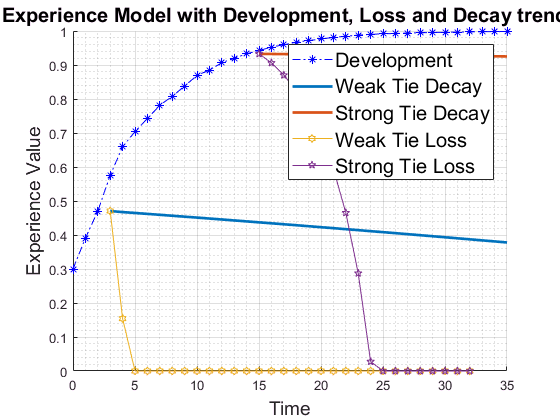

%Experience Model specifies three trends: Development, Loss and Decay
%Experience is normalized in the range [0,1]
%
%--------------------------------------------------------------------
% Randomly create a series of interactions
n = 100;
coop_threshold = 0.6;
uncoop_threshold = 0.3;
interaction = rand(n, 1);

coop_interaction = interaction(interaction > coop_threshold);
uncoop_interaction = interaction(interaction < uncoop_threshold);

exp = zeros(n,0);
exp_start = 0.3;
exp(1) = exp_start;

grid on;
grid minor;
hold on;

% Development Model: let define alpha = maximum increase of Experience
% x(i+1) = x(i) + interaction_value*alpha*(1-x(i));
alpha = 0.2;
for i=1:size(coop_interaction)
    exp(i+1)= exp(i) + coop_interaction(i)*alpha*(1-exp(i));
end
plot(0:size(coop_interaction), exp, 'b-.*');




% Decay Model: let define alpha = maximum increase of Experience
% exp(t+1) = exp(t) - decay
%let set the parameters
min_decay = 0.005;
decay_rate = 0.005;
min_exp = 0;

start_decay = 6;
end_decay = size(coop_interaction);
expd = exp(1:start_decay);
for j=start_decay:end_decay
    expd(j+1) = max(exp_start, expd(j) - min_decay*(1 + decay_rate - expd(j-1)));    
end
plot((start_decay):end_decay, expd(start_decay:end_decay), '-', 'LineWidth',2);
hold on;

%{
start_decay = 10;
end_decay = size(coop_interaction);
expd = exp(1:start_decay);
for j=start_decay:end_decay
    expd(j+1) = max(exp_start, expd(j) - min_decay*(1 + decay_rate - expd(j-1)));    
end
plot((start_decay):end_decay, expd(start_decay:end_decay), 'k-s');
hold on;
%}

start_decay = 15;
end_decay = size(coop_interaction);
expd = exp(1:start_decay);
for j=start_decay:end_decay
    expd(j+1) = max(exp_start, expd(j) - min_decay*(1 + decay_rate - expd(j-1)));    
end
plot((start_decay):end_decay, expd(start_decay:end_decay), '-', 'LineWidth',2);
hold on;

% Loss model
% Specify the Loss Rate
% newExp = max(min_exp, currentExp-loss_rate*(1 - fbValue)*alpha*(1-currentExp));

start_loss = 6;
end_loss = size(uncoop_interaction);
loss_rate = 3;
expl = exp(1:start_loss);
for j=start_loss:end_loss
    expl(j+1) = max(min_exp, expl(j)-loss_rate*(1-uncoop_interaction(j))*alpha*(1-expl(j)));
end
plot((start_loss):end_loss, expl(start_loss:end_loss), '-h');
hold on;

start_loss = 15;
end_loss = size(uncoop_interaction);
loss_rate = 2;
expl = exp(1:start_loss);
for j=start_loss:end_loss
    expl(j+1) = max(min_exp, expl(j)-loss_rate*(1-uncoop_interaction(j))*alpha*(1-expl(j)));
end
plot((start_loss):end_loss, expl(start_loss:end_loss), '-p');
hold off;

%xlim([1 50])
xlabel('Time', 'FontSize',14);
ylabel('Experience Value', 'FontSize',14);
title('Experience Model with Development, Loss and Decay trends', 'FontSize',15);
lgt = legend({'Development','Weak Tie Decay', 'Strong Tie Decay', 'Weak Tie Loss', 'Strong Tie Loss'},'FontSize',15);

%title(lgt, 'Size of the Network');
legend('show');